Question 1

L = 1000 ;
X = (1:L);
D = randi([0 1],L,1);       %generating a random binary sequence of length 1000

%generating a rectangular pulse S
A = 1;
S = zeros(1,L) ;            %generating a zero sequence of length L
for n = 1:L 
    if D(n) == 0 
        S(n) = (-1)*A;      %assigning -A if D(n) equals zero
    else
        S(n) = A ;          %assigning A if D(n) equals one
    end
end

Question 2

mean = 0 ;
var = 1 ;
N = mean + var* randn(1,L);   %generating AWGN with zero mean and variance sigma

Question 3

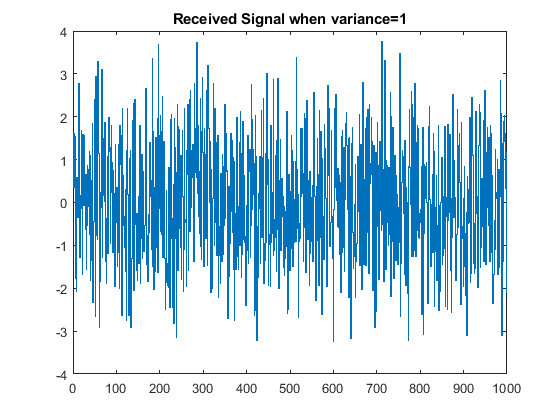

R = S + N  ;                  %generating received signal

%plotting the received signal when variance=1
figure;
stairs(X,R);
title("Received Signal when variance=1");

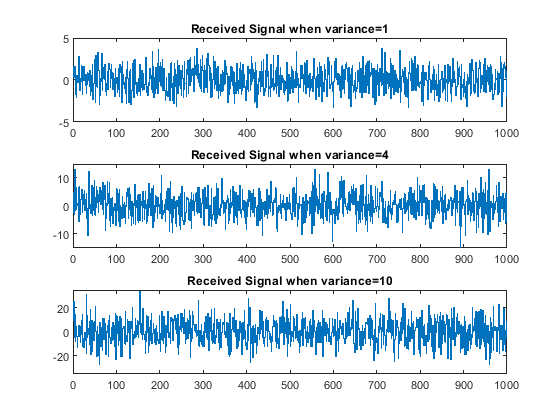

%generating the received signal when variance=4
var1 = 4 ;
N1 = mean + var1* randn(1,L);
R1 = S + N1  ; 

%generating the received signal when variance=10
var2 = 10 ;
N2 = mean + var2* randn(1,L);
R2 = S + N2 ;

%plotting the graphs
figure;
subplot(3,1,1);
stairs(X,R);
title("Received Signal when variance=1");
subplot(3,1,2);
stairs(X,R1);
ylim([-15,15]);
title("Received Signal when variance=4");
subplot(3,1,3);
stairs(X,R2);
ylim([-35,35]);
title("Received Signal when variance=10");

By oberserving the above three plots of received signal with noise variance 1,4 and 10, we can conclude that; when the variance is increased the amplitude of received signal also increases. So the signal get more distorted.

Question 4

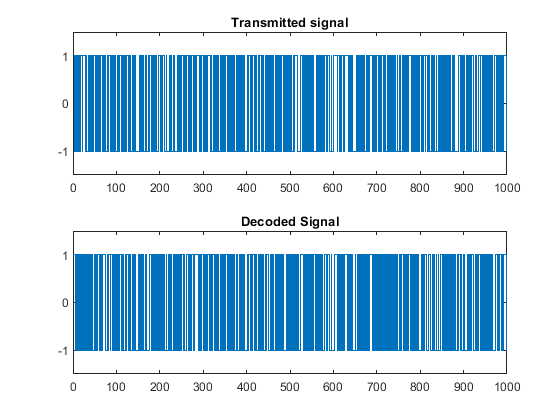

%generating the Y sequence
tau = 0;
Y = zeros(1,L) ;            %generating a zero sequence of length L
for i = 1:L 
    if R(i) <= tau 
        Y(i) = (-1)*A;      %assigning -A if R(i) is lesser than or equal to tau
    else
        Y(i) = A ;          %assigning A if R(i) is greater than tau
    end
end

%plotting the tranmitted signal
figure;
subplot(2,1,1);
stairs(X,S);
ylim([-1.5,1.5]);
title("Transmitted signal");

%plotting sequence of Y
subplot(2,1,2);
stairs(X,Y);
ylim([-1.5,1.5]);
title("Decoded Signal");

To observe the differences between sequence of Y and transmitted signal ,

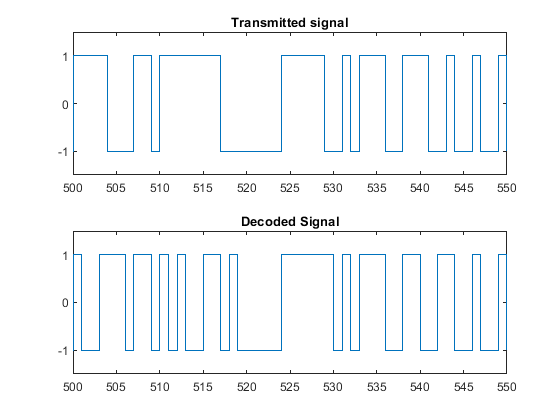

figure;
subplot(2,1,1);
stairs(X,S);
axis([500 550 -1.5 1.5]);
title("Transmitted signal");
subplot(2,1,2);
stairs(X,Y);
axis([500 550 -1.5 1.5]);
title("Decoded Signal");

According to the above two plots, there are a few number of bits which are identified incorrectly. Most of the bits in the decoded signal are same as the transmitted signal.

Question 5

Repeating the above code for L = 100000,

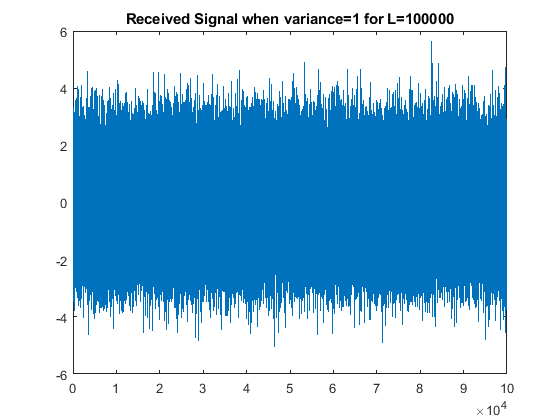

L = 100000 ;
X = (1:L);
D = randi([0 1],L,1);       %generating a random binary sequence of length 1000
A = 1;
S = zeros(1,L) ;            %generating a zero sequence of length L
for n = 1:L 
    if D(n) == 0 
        S(n) = (-1)*A;      %assigning -A if D(n) equals zero
    else
        S(n) = A ;          %assigning A if D(n) equals one
    end
end
mean = 0 ;
var = 1 ;
N = mean + var* randn(1,L);
R = S + N  ;                  %generating received signal
%plotting the received signal when variance=1
figure;
stairs(X,R);
title("Received Signal when variance=1 for L=100000");

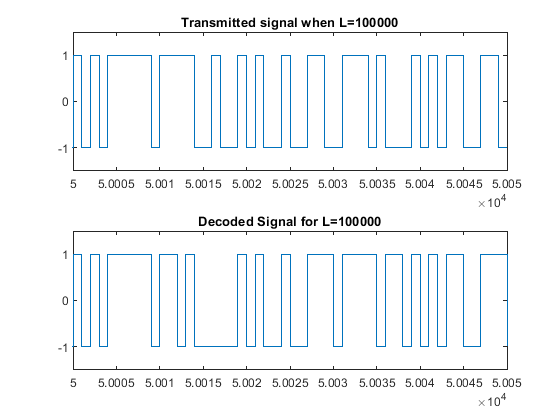

%generating the Y sequence for L = 100000
tau = 0;
Y = zeros(1,L) ;            %generating a zero sequence of length L
for i = 1:L 
    if R(i) <= tau 
        Y(i) = (-1)*A;      %assigning -A if R(i) is lesser than or equal to tau
    else
        Y(i) = A ;          %assigning A if R(i) is greater than tau
    end
end

figure;
subplot(2,1,1);
stairs(X,S);
axis([50000 50050 -1.5 1.5]);
title("Transmitted signal when L=100000");
subplot(2,1,2);
stairs(X,Y);
axis([50000 50050 -1.5 1.5]);
title("Decoded Signal for L=100000");

By comparing above two plots with the two plots for L = 1000, we can obseve higher number of bit errors when L is increased.